# PROF. AMBROSINO R.___ESAME___11/03/2026___SALVATORE_RAIOLA_DE6000008

clear; close all; clc;

## 0)  DEFINIZIONI

#### Variabili simboliche 

syms x1 x2 theta dx1 dx2 dtheta ddx1 ddx2 ddtheta u1 u2 real

#### Parametri

m1 = 1.5;
m2 = 1.0;
mp = 0.25;
l = 0.40;
J = 0.013;
k = 35;
b = 4;
g = 9.81;

#### I-S-U

% Ingresso
u = [u1;
     u2];

% Stato
x = [x1;
     x2;
     theta;
     dx1;
     dx2;
     dtheta];

% Uscita
y = [x1;
     x2;
     theta];

#### Modello Dinamico

eq1_sym = (m1+mp)*ddx1 + mp*l*cos(theta)*ddtheta - mp*l*sin(theta)*dtheta^2 + k*(x1-x2) + b*(dx1-dx2) == u1;
eq2_sym = m2*ddx2 + k*(x2-x1) + b*(dx1-dx2) == u2;
eq3_sym = (J+mp*l^2)*ddtheta + mp*l*cos(theta)*ddx1 - mp*g*l*sin(theta) == 0;

eqs = [eq1_sym;
       eq2_sym;
       eq3_sym];

sol = solve(eqs, [ddx1, ddx2, ddtheta], "ReturnConditions",true);

% dx/dt
f = [dx1;
     dx2;
     dtheta;
     sol.ddx1;
     sol.ddx2;
     sol.ddtheta];

% y
g = y;

## 1)  PUNTI DI EQUILIBRIO E LINEARIZZAZIONE

### 1.1)  Punti di Equilibrio

eq1_peql = subs(eq1_sym, [dx1, dx2, dtheta, ddx1, ddx2, ddtheta, u1, u2], [0, 0, 0, 0, 0, 0, 0, 0]) == 0;
eq2_peql = subs(eq2_sym, [dx1, dx2, dtheta, ddx1, ddx2, ddtheta, u1, u2], [0, 0, 0, 0, 0, 0, 0, 0]) == 0;
eq3_peql = subs(eq3_sym, [dx1, dx2, dtheta, ddx1, ddx2, ddtheta, u1, u2], [0, 0, 0, 0, 0, 0, 0, 0]) == 0;

eqs_peql = [eq1_peql;
            eq2_peql;
            eq3_peql];

peql = solve(eqs_peql, [x1, x2, theta], "ReturnConditions",true);

%x1_star = double(peql.x1);
%x2_star = double(peql.x2);
%theta_star = double(peql.theta);
dx1_star = 0;
dx2_star = 0;
dtheta_star = 0;

disp(table(peql.x1, peql.x2, peql.theta, dx1_star, dx2_star, dtheta_star));

    Var1    Var2    Var3    Var4    Var5    Var6
    ____    ____    ____    ____    ____    ____

     x       y      pi*k     0       0       0  



### 1.2)  Modello LInearizzato nell'intorno di x=0 e u=0

A_sym = jacobian(f,x);
B_sym = jacobian(f,u);
C_sym = jacobian(g,x);
D_sym = jacobian(g,u);

A = double(subs(A_sym, [x1, x2, theta, dx1, dx2, dtheta, u1, u2], [0, 0, 0, 0, 0, 0, 0, 0]));
B = double(subs(B_sym, [x1, x2, theta, dx1, dx2, dtheta, u1, u2], [0, 0, 0, 0, 0, 0, 0, 0]));
C = double(subs(C_sym, [x1, x2, theta, dx1, dx2, dtheta, u1, u2], [0, 0, 0, 0, 0, 0, 0, 0]));
D = double(subs(D_sym, [x1, x2, theta, dx1, dx2, dtheta, u1, u2], [0, 0, 0, 0, 0, 0, 0, 0]));

n = size(A,1);
m = size(B,2);

sys = ss(A, B, C, D)


sys =
 
  A = 
           x1      x2      x3      x4      x5      x6
   x1       0       0       0       1       0       0
   x2       0       0       0       0       1       0
   x3       0       0       0       0       0       1
   x4  -22.42   22.42  -1.185  -2.562   2.562       0
   x5      35     -35       0      -4       4       0
   x6    42.3   -42.3   20.75   4.834  -4.834       0
 
  B = 
           u1      u2
   x1       0       0
   x2       0       0
   x3       0       0
   x4  0.6405       0
   x5       0       1
   x6  -1.208       0
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   1   0   0   0   0   0
   y2   0   1   0   0   0   0
   y3   0   0   1   0   0   0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
   y3   0   0
 
Continuous-time state-space model.


### 1.3)  Controllabilità e Osservabilità

#### Controllabilità

if rank(ctrb(A,B)) == n
    disp('Il sistema è completamente Controllabile');
else
    disp('Il sistema NON è completamente Controllabile');
end

Il sistema è completamente Controllabile


#### Osservabilità

if rank(obsv(A,C)) == n
    disp('Il sistema è completamente Osservabile');
else
    disp('Il sistema NON è completamente Osservabile');
end

Il sistema è completamente Osservabile


## 2)  APPROCCIO ALLA LYAPUNOV

#### Specifiche

alpha_LMI = 5.0;

#### Risoluzione con CVX

cvx_clear;
cvx_begin sdp quiet
    cvx_precision high
    variable Q(n,n) symmetric
    variable L(m,n)

    minimize (0);

    subject to
    Q >= 1e-6*eye(n);
    A*Q + Q*A' + B*L + L'*B' + 2*alpha_LMI*Q <= 1e-6*eye(n);
cvx_end

K_LMI = -L/Q

K_LMI = 1.0e+03 *

   -1.4019   -0.0153   -1.4222   -0.5356    0.0002   -0.3144
   -0.5420    0.2147   -0.4780   -0.1794    0.0281   -0.1073


#### Verifica Matlab

sys_cl_LMI = ss((A-B*K_LMI), B, C, D);

eig(A-B*K_LMI)

ans =  -15.2421 +19.0876i
 -15.2421 -19.0876i
 -10.4494 + 8.9910i
 -10.4494 - 8.9910i
  -6.1237 + 1.1040i
  -6.1237 - 1.1040i


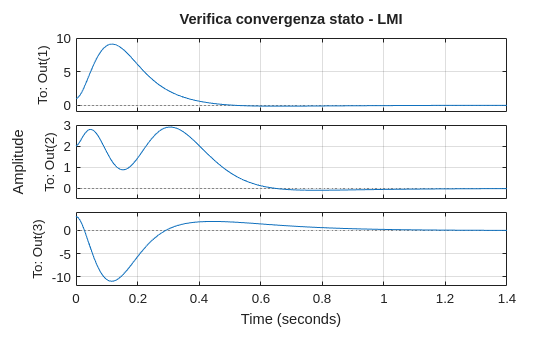

% supponiamo uno stato iniziale diverso da 0
x0_LMI = [1;
          2;
          3;
          4;
          5;
          6];

figure;
initial(sys_cl_LMI, x0_LMI);
grid on;
title('Verifica convergenza stato - LMI');

## 3)  ASSEGNAMENTO AUTOVALORI

#### Specifiche

% Stato inziale
x0_EIG = [0.05;
          -0.05;
          deg2rad(10);
          0;
          0;
          0];

% Riferimento
x_ref_EIG = [0.15;
             0.15;
             0];

% Tempo di Assestamento
Ts = 10;

#### Sintesi

alpha_EIG = 4/Ts;
sigma_dominante = alpha_EIG + 0.1;

p1 = -sigma_dominante;
p2 = p1-0.5;
p3 = -5*sigma_dominante;
p4 = p3-0.01;
p5 = p4-0.01;
p6 = p5-0.01;

eig_des = [p1, p2, p3, p4, p5, p6];

K_EIG = -place(A, B, eig_des)

K_EIG =    35.2669  -34.9935   29.1947    5.0123   -3.9974    5.9382
  -35.3308   28.6692   -4.5037    3.2524   -9.0323   -1.1618


sys_cl_EIG = ss((A-B*K_EIG), B, C, D);

gain = dcgain(sys_cl_EIG);

N = pinv(gain)

N =    70.2669  -69.9935    0.0000
  -70.3308   63.6692   -0.0000


C_tot = [C;
         zeros(3,6)];

D_tot = [D;
         zeros(3,2)];